# Experiment 7.1

## Name: John McAvoy

## Objectives

To verify the effect of input waveform, loop gain, and system type upon steady-state errors.

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*What system types will yield zero steady-state error for step inputs?*

**Answer:**

Type 1 and 2 sytems

### Problem 2

*What system types will yield zero steady-state error for ramp inputs?*

**Answer:**

Type 2

### Problem 3

*What system types will yield infinite steady-state error for ramp inputs?*

**Answer:**

Types 0

### Problem 4

*What system types will yield zero steady-state error for parabolic inputs?*

**Answer:**

Type 3 and higher

### Problem 5

*What system types will yield infinite steady-state error for parabolic inputs?*

**Answer:**

Types 0 and 1

### Problem 6

*For the negative feedback system of Figure P6.19 where*$G(s) = \frac{K(s+6)}{(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$, calculate the steady-state error in terms of $K$ for the following inputs: $5u(t)$, $5tu(t)$, and $5t^2u(t)$. 

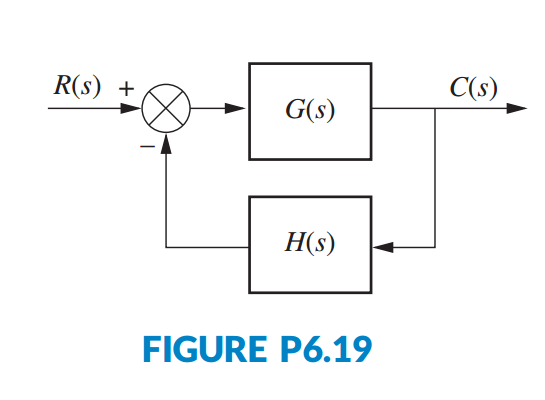

**Answer:**

$\frac{1}{1+\frac{30K}{3024}}$, 0 , 0

### Problem 7

*Repeat Prelab 6 for *$G(s) = \frac{K(s+6)(s+8)}{s(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$.

**Answer:**

$\infty$$\frac{3024}{240K}$,0

### Problem 8

*Repeat Prelab 6 for *$G(s) = \frac{K(s+1)(s+6)(s+8)}{s^2(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$.

**Answer:**

$\infty$,$\infty$,$\frac{3024}{120K}$

## Lab

### Problem 1

*Using Simulink, set up the negative feedback system of Prelab 6. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$=50, 500, 1000, and 5000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

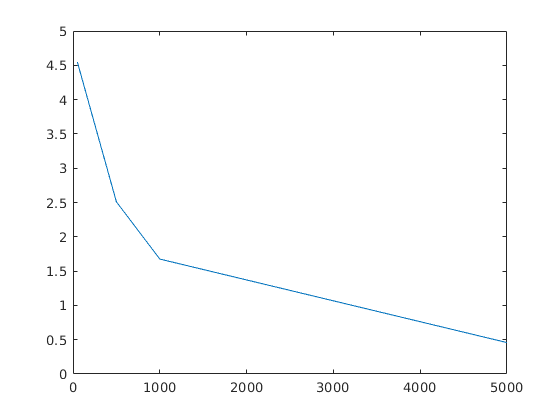

% P1
%  print('-sP1','-dpng','P1.png');

syms s
K = [50 500 1000 5000];

for i=1:4
    G = (K(i) * (s+6))/ ( (s+4)*(s+7)*(s+9)*(s+12));
    
    Kp = limit(G,s,0);
    e_ss0(i) = 5 /( 1 + Kp);

    Kv = limit((5*s*G),s,0);
    e_ss1(i) = 1 /(Kv);

    Ka = limit(5/2*s^2*G,s,0);
    e_ss2(i) = 1 /(Ka);
end
plot(K,e_ss0)

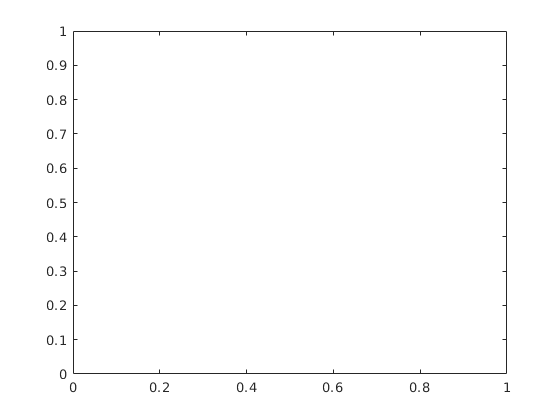

plot(K,e_ss1)

plot(K,e_ss2)

### Problem 2

*Using Simulink, set up the negative feedback system of Prelab 7. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$=50, 500, 1000, and 5000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

%  P2
%  print('-sP2','-dpng','P2.png');

syms s
K = [50 500 1000 5000];

for i=1:4
    G = (K(i) * (s+6) * (s+8)) / ( s*(s+4)*(s+7)*(s+9)*(s+12));
    
    Kp = limit(G,s,0);
    e_ss0(i) = 5 /( 1 + Kp);

    Kv = limit((5*s*G),s,0);
    e_ss1(i) = 1 /(Kv);

    Ka = limit(5/2*s^2*G,s,0);
    e_ss2(i) = 1 /(Ka);
end
plot(K,e_ss0)

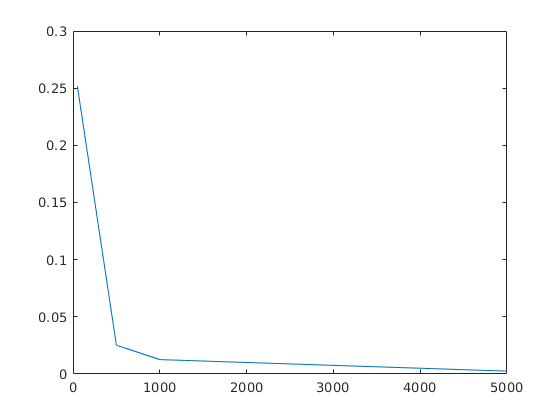

plot(K,e_ss1)

plot(K,e_ss2)

### Problem 3

*Using Simulink, set up the negative feedback system of Prelab 8. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$= 200, 400, 800, and 1000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

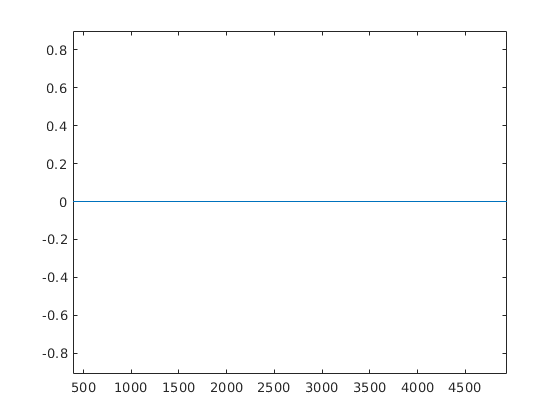

%  P3
%  print('-sP3','-dpng','P3.png');

syms s
K = [50 500 1000 5000];

for i=1:4
    G = (K(i) * (s+1) * (s+6) * (s+8)) / ( s^2 *(s+4)*(s+7)*(s+9)*(s+12));
    
    Kp = limit(G,s,0);
    e_ss0(i) = 5 /( 1 + Kp);

    Kv = limit((5*s*G),s,0);
    e_ss1(i) = 1 /(Kv);

    Ka = limit(5/2*s^2*G,s,0);
    e_ss2(i) = 1 /(Ka);
end
plot(K,e_ss0)

xlim([390 4936])
ylim([-0.91 0.90])

plot(K,e_ss1)

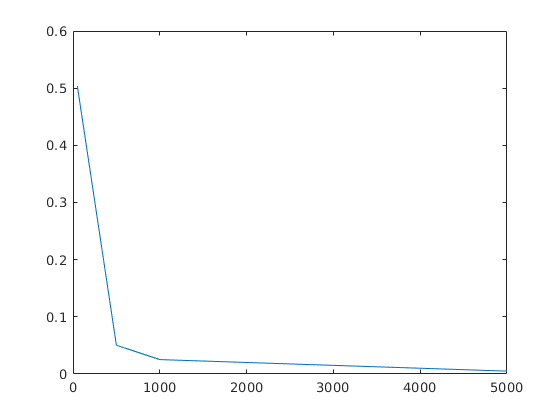

plot(K,e_ss2)

## Postlab

### Problem 1

*Use your plots from Lab 1 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

The steady state errors calculated in prelab 1 matched the steady state errors in problem 1.

### Problem 2

*Use your plots from Lab 2 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

The steady state errors calculated in prelab 2 matched the steady state errors in problem 2.

### Problem 3

*Use your plots from Lab 3 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

The steady state errors calculated in prelab 3 matched the steady state errors in problem 3.